# EPIPOLAR LINE REAL TEST

ports = serialportlist;
openmv1=0;
openmv2=0;
openmv1 = serialport('/dev/tty.usbserial-0001',115200)

openmv1 =   Serialport with properties:

                 Port: "/dev/tty.usbserial-0001"
             BaudRate: 115200
    NumBytesAvailable: 0

  Show all properties, functions


openmv2 = serialport('/dev/tty.usbserial-3',115200)

openmv2 =   Serialport with properties:

                 Port: "/dev/tty.usbserial-3"
             BaudRate: 115200
    NumBytesAvailable: 0

  Show all properties, functions


Step 2: Intrinisc parameters

openmv1.write('INT','string')
openmv2.write('INT','string')
camID1 = extractAfter(openmv1.readline(),'0')

camID1 = "1"

camID2 = extractAfter(openmv2.readline(),'0')

camID2 = "3"


filepath1_1 = ['/Users/ferialmeyer/Documents/Zak - UCT Stuff/MATLAB INTRINSIC PARAMS/CAM',num2str(camID1),'/CAM',num2str(camID1),'Params_GRAYSCALE.mat'];
filepath1_2 = ['/Users/ferialmeyer/Documents/Zak - UCT Stuff/MATLAB INTRINSIC PARAMS/CAM',num2str(camID1),'/CAM',num2str(camID1),'Params_RGB.mat'];
file1_1 = load(filepath1_1);
file1_2 = load(filepath1_2);
cInt1 = file1_1.cameraParams;
calibInt1 = file1_2.cameraParams;

filepath1_1 = ['/Users/ferialmeyer/Documents/Zak - UCT Stuff/MATLAB INTRINSIC PARAMS/CAM',num2str(camID2),'/CAM',num2str(camID2),'Params_GRAYSCALE.mat'];
filepath1_2 = ['/Users/ferialmeyer/Documents/Zak - UCT Stuff/MATLAB INTRINSIC PARAMS/CAM',num2str(camID2),'/CAM',num2str(camID2),'Params_RGB.mat'];
file1_1 = load(filepath1_1);
file1_2 = load(filepath1_2);
cInt2 = file1_1.cameraParams;
calibInt2 = file1_2.cameraParams;

cInt1

cInt1 =   cameraParameters with properties:

   Camera Intrinsics
                         Intrinsics: [1×1 cameraIntrinsics]

   Camera Extrinsics
                  PatternExtrinsics: [18×1 rigidtform3d]

   Accuracy of Estimation
              MeanReprojectionError: 0.2189
                 ReprojectionErrors: [48×2×18 double]
                  ReprojectedPoints: [48×2×18 double]

   Calibration Settings
                        NumPatterns: 18
                  DetectedKeypoints: [48×18 logical]
                        WorldPoints: [48×2 double]
                         WorldUnits: 'millimeters'
                       EstimateSkew: 0
    NumRadialDistortionCoefficients: 2
       EstimateTangentialDistortion: 0


cInt2

cInt2 =   cameraParameters with properties:

   Camera Intrinsics
                         Intrinsics: [1×1 cameraIntrinsics]

   Camera Extrinsics
                  PatternExtrinsics: [20×1 rigidtform3d]

   Accuracy of Estimation
              MeanReprojectionError: 0.2039
                 ReprojectionErrors: [35×2×20 double]
                  ReprojectedPoints: [35×2×20 double]

   Calibration Settings
                        NumPatterns: 20
                  DetectedKeypoints: [35×20 logical]
                        WorldPoints: [35×2 double]
                         WorldUnits: 'millimeters'
                       EstimateSkew: 0
    NumRadialDistortionCoefficients: 3
       EstimateTangentialDistortion: 0


calibInt1

calibInt1 =   cameraParameters with properties:

   Camera Intrinsics
                         Intrinsics: [1×1 cameraIntrinsics]

   Camera Extrinsics
                  PatternExtrinsics: [23×1 rigidtform3d]

   Accuracy of Estimation
              MeanReprojectionError: 0.1293
                 ReprojectionErrors: [35×2×23 double]
                  ReprojectedPoints: [35×2×23 double]

   Calibration Settings
                        NumPatterns: 23
                  DetectedKeypoints: [35×23 logical]
                        WorldPoints: [35×2 double]
                         WorldUnits: 'millimeters'
                       EstimateSkew: 0
    NumRadialDistortionCoefficients: 2
       EstimateTangentialDistortion: 0


calibInt2

calibInt2 =   cameraParameters with properties:

   Camera Intrinsics
                         Intrinsics: [1×1 cameraIntrinsics]

   Camera Extrinsics
                  PatternExtrinsics: [14×1 rigidtform3d]

   Accuracy of Estimation
              MeanReprojectionError: 0.1221
                 ReprojectionErrors: [35×2×14 double]
                  ReprojectedPoints: [35×2×14 double]

   Calibration Settings
                        NumPatterns: 14
                  DetectedKeypoints: [35×14 logical]
                        WorldPoints: [35×2 double]
                         WorldUnits: 'millimeters'
                       EstimateSkew: 0
    NumRadialDistortionCoefficients: 3
       EstimateTangentialDistortion: 0


Step 3: Extrinsic parameters

3a: Set world points

F1_B = [-0.12 0.12]; %RED
F2_B = [0.12 -0.12]; %GREEN
F3_B = [0.12 0.12]; %BLUE
F4_B = [-0.12 -0.12]; %PURPLE
F5_B = [-0.12 0]; %WHITE
F6_B = [0 0.12]; %CYAN

worldPoints = [F1_B;F2_B;F3_B;F4_B;F5_B];%F6_B];

3b(1): Get pixel location data of worldpoints - RGB

openmv1.write('EXT_RGB','string')
flush(openmv1)
pause(0.1)
extData1 = openmv1.readline()

extData1 = "128,213,137,147,93,173,176,182,153,197"

myData1 = str2double(split(extData1,','))

myData1 =    128
   213
   137
   147
    93
   173
   176
   182
   153
   197


UV1_1 = [myData1(1) myData1(2)];
UV1_2 = [myData1(3) myData1(4)];
UV1_3 = [myData1(5) myData1(6)];
UV1_4 = [myData1(7) myData1(8)];
UV1_5 = [myData1(9) myData1(10)];
% UV1_6 = [myData1(11) myData1(12)];
imagePoints1_RGB = [UV1_1;UV1_2;UV1_3;UV1_4;UV1_5];%UV1_6]

openmv2.write('EXT_RGB','string')
flush(openmv2)
pause(0.1)
extData2 = openmv2.readline()

extData2 = "171,206,256,160,189,144,248,221,208,215"

myData2 = str2double(split(extData2,','))

myData2 =    171
   206
   256
   160
   189
   144
   248
   221
   208
   215


UV2_1 = [myData2(1) myData2(2)];
UV2_2 = [myData2(3) myData2(4)];
UV2_3 = [myData2(5) myData2(6)];
UV2_4 = [myData2(7) myData2(8)];
UV2_5 = [myData2(9) myData2(10)];
% UV2_6 = [myData2(11) myData2(12)];
imagePoints2_RGB = [UV2_1;UV2_2;UV2_3;UV2_4;UV2_5];%UV2_6]


%NORMALIZE IMAGE POINTS > 0<=imagePoint*<=1
normRGB_imagePoints1 = [imagePoints1_RGB(:,1)/calibInt1.ImageSize(2) imagePoints1_RGB(:,2)/calibInt1.ImageSize(1)]

normRGB_imagePoints1 =     0.4000    0.8875
    0.4281    0.6125
    0.2906    0.7208
    0.5500    0.7583
    0.4781    0.8208


normRGB_imagePoints2 = [imagePoints2_RGB(:,1)/calibInt2.ImageSize(2) imagePoints2_RGB(:,2)/calibInt2.ImageSize(1)]

normRGB_imagePoints2 =     0.5344    0.8583
    0.8000    0.6667
    0.5906    0.6000
    0.7750    0.9208
    0.6500    0.8958



openmv1.write('EXT_RGB_SUCCESS','string');
openmv2.write('EXT_RGB_SUCCESS','string');

3b(2): Get pixel location data of worldpoints - 

flush(openmv1)
flush(openmv2)

openmv1.write('EXT_GRAY','string')
extData1 = openmv1.readline()

extData1 = "279,290,181,342,359,364,309,394,258,427,0.974659"

myData1 = str2double(split(extData1,','))

myData1 =    279
   290
   181
   342
   359
   364
   309
   394
   258
   427


UV1_1 = [myData1(1) myData1(2)];
UV1_2 = [myData1(3) myData1(4)];
UV1_3 = [myData1(5) myData1(6)];
UV1_4 = [myData1(7) myData1(8)];
UV1_5 = [myData1(9) myData1(10)];
% UV1_6 = [myData1(11) myData1(12)];
imagePoints1_GRAY = [UV1_1;UV1_2;UV1_3;UV1_4;UV1_5];%UV1_6]

openmv2.write('EXT_GRAY','string')
extData2 = openmv2.readline()

extData2 = "379,286,516,320,339,412,417,432,494,450,0.974659"

myData2 = str2double(split(extData2,','))

myData2 =    379
   286
   516
   320
   339
   412
   417
   432
   494
   450


UV2_1 = [myData2(1) myData2(2)];
UV2_2 = [myData2(3) myData2(4)];
UV2_3 = [myData2(5) myData2(6)];
UV2_4 = [myData2(7) myData2(8)];
UV2_5 = [myData2(9) myData2(10)];
% UV2_6 = [myData2(11) myData2(12)];
imagePoints2_GRAY = [UV2_1;UV2_2;UV2_3;UV2_4;UV2_5];%UV2_6]


%NORMALIZE IMAGE POINTS > 0<=imagePoint*<=1
normGRAY_imagePoints1 = [imagePoints1_GRAY(:,1)/cInt1.ImageSize(2) imagePoints1_GRAY(:,2)/cInt1.ImageSize(1)]

normGRAY_imagePoints1 =     0.4359    0.6042
    0.2828    0.7125
    0.5609    0.7583
    0.4828    0.8208
    0.4031    0.8896


normGRAY_imagePoints2 = [imagePoints2_GRAY(:,1)/cInt2.ImageSize(2) imagePoints2_GRAY(:,2)/cInt2.ImageSize(1)]

normGRAY_imagePoints2 =     0.5922    0.5958
    0.8063    0.6667
    0.5297    0.8583
    0.6516    0.9000
    0.7719    0.9375


openmv1.write('EXT_GRAY_SUCCESS','string');
openmv2.write('EXT_GRAY_SUCCESS','string');

%C1
imagePoints1_distorted = zeros(5,2);
for k = 1:5
   smallest_diff = [1 1];
   for i = 1:5
       norm_diff = abs(normRGB_imagePoints1(k,:) - normGRAY_imagePoints1(i,:));
       if sqrt(norm_diff(1)^2+norm_diff(2)^2) < sqrt(smallest_diff(1)^2+smallest_diff(2)^2)
            pos = i;
            smallest_diff = norm_diff;
       end
   end
   imagePoints1_distorted(k,:) = imagePoints1_GRAY(pos,:);
end

imagePoints1_undistorted = zeros(5,2);
for k = 1:5
    imagePoints1_undistorted(k,:) = undistortPoints(imagePoints1_distorted(k,:),cInt1);
end
    imagePoints1_undistorted = imagePoints1_undistorted(1:5,:)

imagePoints1_undistorted =   257.6327  427.9449
  278.9644  289.8865
  179.4419  342.0847
  359.3593  364.1540
  309.0605  394.2254


extrinsics_1 = estimateExtrinsics(imagePoints1_undistorted,worldPoints,cInt1.Intrinsics);
camPose_1 = extr2pose(extrinsics_1)

camPose_1 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.5829 0.4759 0.9999]
                 R: [3×3 double]
                 A: [4×4 double]



%C2
imagePoints2_distorted = zeros(5,2);
for k = 1:5
   smallest_diff = [1 1];
   for i = 1:5
       norm_diff = abs(normRGB_imagePoints2(k,:) - normGRAY_imagePoints2(i,:));
       if sqrt(norm_diff(1)^2+norm_diff(2)^2) < sqrt(smallest_diff(1)^2+smallest_diff(2)^2)
            pos = i;
            smallest_diff = norm_diff;
       end
   end
   imagePoints2_distorted(k,:) = imagePoints2_GRAY(pos,:);
end

imagePoints2_undistorted = zeros(5,2);
for k = 1:5
    imagePoints2_undistorted(k,:) = undistortPoints(imagePoints2_distorted(k,:),cInt2);
end
imagePoints2_undistorted = imagePoints2_undistorted(1:5,:)

imagePoints2_undistorted =   338.1979  419.7807
  522.5293  323.8178
  379.0945  286.2628
  506.0433  469.6939
  420.3407  443.5741


extrinsics_2 = estimateExtrinsics(imagePoints2_undistorted,worldPoints,cInt2.Intrinsics);
camPose_2 = extr2pose(extrinsics_2)

camPose_2 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.5146 0.0156 0.8482]
                 R: [3×3 double]
                 A: [4×4 double]



BP_UV_1 = world2img([worldPoints zeros(5,1)], rigidtform3d(extrinsics_1.A), cInt1.Intrinsics)

BP_UV_1 =   256.1725  429.9881
  279.5669  288.1560
  180.9222  342.7095
  357.4287  363.5098
  308.9462  395.3403


DIFF_1 = abs(imagePoints1_undistorted - BP_UV_1)

DIFF_1 =     1.4602    2.0431
    0.6026    1.7306
    1.4803    0.6248
    1.9306    0.6442
    0.1143    1.1149



BP_UV_2 = world2img([worldPoints zeros(5,1)], rigidtform3d(extrinsics_2.A), cInt2.Intrinsics)

BP_UV_2 =   334.9867  419.6191
  525.3204  323.7467
  378.0168  286.7298
  507.2151  468.8206
  419.3626  443.7233


DIFF_2 = abs(imagePoints2_undistorted - BP_UV_2)

DIFF_2 =     3.2112    0.1616
    2.7911    0.0712
    1.0777    0.4671
    1.1717    0.8733
    0.9782    0.1492


%OPTIMIZING EXTRINSICS
%CAMERA 1:
%---------------------------------------------
%% Optimize Extrinsic Parameters (Camera Pose)

% This script optimizes the camera's extrinsic parameters to minimize reprojection error.

% Load or Define Intrinsic Camera Parameters
% Replace with your camera's intrinsic parameters
cameraParams = cInt1; % This should be a cameraParameters object or similar

% Define 3D World Points
% Replace these with your 3D points
worldPoints1 = [worldPoints zeros(5,1)]; % Nx3 matrix [X, Y, Z]

% Define Corresponding 2D Image Points
% Replace these with your 2D points
imagePoints = imagePoints1_undistorted(1:5,:); % Nx2 matrix [x, y]

%% Define the Residual Function
% Function that computes the reprojection error for given pose parameters

residualFunc = @(pose) computeReprojectionError(pose, worldPoints1, imagePoints, cameraParams);

%% Initial Guess for Pose Parameters
% Provide a reasonable initial guess for [rx, ry, rz, tx, ty, tz]
% rx, ry, rz are rotation angles (in radians), and tx, ty, tz are translations
eulAng = rotm2eul(extrinsics_1.R)

eulAng =    -2.3533   -0.4773   -2.6465


initialPose = [eulAng , extrinsics_1.Translation(1), extrinsics_1.Translation(2), extrinsics_1.Translation(3)]; % Adjust this based on your initial estimate

%% Perform Nonlinear Least Squares Optimization
options = optimoptions('lsqnonlin', 'Display', 'iter'); % Display iteration output
optimizedPose_1 = lsqnonlin(residualFunc, initialPose, [], [], options);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          7           17.6443                              933
     1         14           2.67393       0.0724644             68.9      
     2         21           2.61156      0.00255081           0.0917      
     3         28           2.61156     1.19483e-05         0.000173      

Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


%-------------------------------
%CAMERA 2:
%-------------------------------
%% Optimize Extrinsic Parameters (Camera Pose)

% This script optimizes the camera's extrinsic parameters to minimize reprojection error.

% Load or Define Intrinsic Camera Parameters
% Replace with your camera's intrinsic parameters
cameraParams = cInt2; % This should be a cameraParameters object or similar

% Define 3D World Points
% Replace these with your 3D points
worldPoints1 = [worldPoints zeros(5,1)]; % Nx3 matrix [X, Y, Z]

% Define Corresponding 2D Image Points
% Replace these with your 2D points
imagePoints = imagePoints2_undistorted(1:5,:); % Nx2 matrix [x, y]

%% Define the Residual Function
% Function that computes the reprojection error for given pose parameters

residualFunc = @(pose) computeReprojectionError(pose, worldPoints1, imagePoints, cameraParams);

%% Initial Guess for Pose Parameters
% Provide a reasonable initial guess for [rx, ry, rz, tx, ty, tz]
% rx, ry, rz are rotation angles (in radians), and tx, ty, tz are translations
eulAng = rotm2eul(extrinsics_2.R)

eulAng =    -1.2069   -0.7137    2.9434


initialPose = [eulAng , extrinsics_2.Translation(1), extrinsics_2.Translation(2), extrinsics_2.Translation(3)]; % Adjust this based on your initial estimate

%% Perform Nonlinear Least Squares Optimization
options = optimoptions('lsqnonlin', 'Display', 'iter'); % Display iteration output
optimizedPose_2 = lsqnonlin(residualFunc, initialPose, [], [], options);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          7           22.6275                         1.04e+03
     1         14           2.03886       0.0677862             79.6      
     2         21           1.95554      0.00247779            0.124      
     3         28           1.95554      3.7214e-05          0.00182      
     4         35           1.95554     5.02408e-07          2.3e-05      

Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteri

%-----------------------------------------------------------------------------


R_1 = eul2rotm(optimizedPose_1(1:3))

R_1 =    -0.6341   -0.7697    0.0743
   -0.6094    0.4382   -0.6608
    0.4761   -0.4643   -0.7468


R_2 = eul2rotm(optimizedPose_2(1:3))

R_2 =     0.2597   -0.9628    0.0749
   -0.7305   -0.2466   -0.6369
    0.6316    0.1107   -0.7673


t_1 = optimizedPose_1(4:6)

t_1 =    -0.0459    0.0318    1.2323


t_2 = optimizedPose_2(4:6)

t_2 =     0.1185    0.2130    0.9823



A_1 = [R_1 t_1'; 0 0 0 1]

A_1 =    -0.6341   -0.7697    0.0743   -0.0459
   -0.6094    0.4382   -0.6608    0.0318
    0.4761   -0.4643   -0.7468    1.2323
         0         0         0    1.0000


A_2 = [R_2 t_2'; 0 0 0 1]

A_2 =     0.2597   -0.9628    0.0749    0.1185
   -0.7305   -0.2466   -0.6369    0.2130
    0.6316    0.1107   -0.7673    0.9823
         0         0         0    1.0000



extrinsics_1.A = A_1

extrinsics_1 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.0459 0.0318 1.2323]
                 R: [3×3 double]
                 A: [4×4 double]


extrinsics_1.R = R_1

extrinsics_1 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.0459 0.0318 1.2323]
                 R: [3×3 double]
                 A: [4×4 double]


extrinsics_1.Translation = t_1

extrinsics_1 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.0459 0.0318 1.2323]
                 R: [3×3 double]
                 A: [4×4 double]


camPose_1 = extr2pose(extrinsics_1)

camPose_1 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.5964 0.5229 0.9447]
                 R: [3×3 double]
                 A: [4×4 double]



extrinsics_2.A = A_2

extrinsics_2 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.1185 0.2130 0.9823]
                 R: [3×3 double]
                 A: [4×4 double]


extrinsics_2.R = R_2

extrinsics_2 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.1185 0.2130 0.9823]
                 R: [3×3 double]
                 A: [4×4 double]


extrinsics_2.Translation = t_2

extrinsics_2 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.1185 0.2130 0.9823]
                 R: [3×3 double]
                 A: [4×4 double]


camPose_2 = extr2pose(extrinsics_2)

camPose_2 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.4957 0.0579 0.8805]
                 R: [3×3 double]
                 A: [4×4 double]




BP_UV_1 = world2img([worldPoints zeros(5,1)], rigidtform3d(extrinsics_1.A), cInt1.Intrinsics)

BP_UV_1 =   257.0130  428.1343
  278.9839  290.1044
  179.5386  341.8603
  358.6759  363.7635
  310.2544  394.4229


DIFF_1 = abs(imagePoints1_undistorted - BP_UV_1)

DIFF_1 =     0.6198    0.1894
    0.0195    0.2179
    0.0966    0.2244
    0.6833    0.3905
    1.1940    0.1975



BP_UV_2 = world2img([worldPoints zeros(5,1)], rigidtform3d(extrinsics_2.A), cInt2.Intrinsics)

BP_UV_2 =   338.0932  419.9283
  523.0446  324.3735
  378.7344  285.9253
  505.6877  468.8883
  420.6624  444.0496


DIFF_2 = abs(imagePoints2_undistorted - BP_UV_2)

DIFF_2 =     0.1047    0.1476
    0.5153    0.5557
    0.3600    0.3374
    0.3557    0.8056
    0.3216    0.4755


flush(openmv1)
flush(openmv2)
pause(1)
for k = 1:1
    openmv1.write('READY','string')
    cam1_data = openmv1.readline()
    openmv2.write('READY','string')
    cam2_data = openmv2.readline()
end

cam1_data = "436,210,79,289,269,438,11.1498"

cam2_data = "229,118,164,285,411,319,11.1498"

camPose_1.A

ans =    -0.9065    0.4062   -0.1152    0.0629
    0.3978    0.7303   -0.5554    0.3050
   -0.1414   -0.5493   -0.8236    0.4732
         0         0         0    1.0000


camPose_2.A

ans =    -0.6224   -0.6581    0.4236   -0.2085
   -0.7825    0.5107   -0.3563    0.2899
    0.0182   -0.5532   -0.8329    0.4983
         0         0         0    1.0000


%BACK PROJECTION CHECK!
%MODEL CHECK
T_1 = camPose_1.A

T_1 =    -0.5818    0.7338   -0.3508    0.1454
    0.7985    0.4331   -0.4182    0.2866
   -0.1550   -0.5234   -0.8379    0.4742
         0         0         0    1.0000


T_2 = camPose_2.A

T_2 =    -0.9852   -0.1373    0.1024   -0.1099
   -0.1702    0.8521   -0.4949    0.4128
   -0.0193   -0.5050   -0.8629    0.5119
         0         0         0    1.0000


invT_1 = T_1\eye(4);
invT_2 = T_2\eye(4);
K1 = [cInt1.K zeros(3,1)];
K2 = [cInt2.K zeros(3,1)];
% K1 = K1*1.9e-16
% K2 = K2*1.9e-16
% K1(3,3)=1
% K2(3,3)=1
C1 = K1*invT_1;
% C1 = C1/C1(3,4);
C2 = K2*invT_2;
% C2 = C2/C2(3,4);

BP_UVW_C1 = C1*[F4_B';0;1];
BP_UV_C1 = BP_UVW_C1/BP_UVW_C1(3);
BP_UV_C1 = BP_UV_C1(1:2)

BP_UV_C1 =   231.0098
  110.5450



BP_UVW_C2 = C2*[F4_B';0;1];
BP_UV_C2 = BP_UVW_C2/BP_UVW_C2(3);
BP_UV_C2 = BP_UV_C2(1:2)

BP_UV_C2 =   437.3362
  129.5744


%COMPARE WITH ACTUAL VALUES
openmv1.write('READY','string');
cam1_data = str2double(split(openmv1.readline(),','));
openmv2.write('READY','string');
cam2_data = str2double(split(openmv2.readline(),','));
UV_C1 = undistortPoints([cam1_data(1) cam1_data(2)],cInt1)'

UV_C1 =   231.3011
  108.5371


UV_C2 = undistortPoints([cam2_data(1) cam2_data(2)],cInt2)'

UV_C2 =   438.7501
  128.5772



%DIFFERENCE 
DIFF_1 = abs(UV_C1 - BP_UV_C1)

DIFF_1 =     0.2913
    2.0080


DIFF_2 = abs(UV_C2 - BP_UV_C2)

DIFF_2 =     1.4140
    0.9973


Epipolar lines:

%GRAB DATA
% openmv1.write('READY','string');
% cam1_data = str2double(split(openmv1.readline(),','));
% openmv2.write('READY','string');
% cam2_data = str2double(split(openmv2.readline(),','));
% UV_C1 = undistortPoints([cam1_data(1) cam1_data(2)],cInt1)'
% UV_C2 = undistortPoints([cam2_data(1) cam2_data(2)],cInt2)'

% Define the camera intrinsics and extrinsics
% Replace these with your actual values
K1 = cInt1.K; % Intrinsic matrix of Camera 1
K2 = cInt2.K; % Intrinsic matrix of Camera 2
R1 = camPose_1.R; % Rotation matrix of Camera 1 w.r.t world frame
R2 = camPose_2.R; % Rotation matrix of Camera 2 w.r.t world frame
t1 = camPose_1.Translation'; % Translation vector of Camera 1 w.r.t world frame
t2 = camPose_2.Translation'; % Translation vector of Camera 2 w.r.t world frame

% Define the UV pixel coordinates from both cameras
% Replace these with your actual values
UV1 = UV_C1 % Pixel coordinates in Camera 1

UV1 =   359.3593
  364.1540


UV2 = UV_C2 % Pixel coordinates in Camera 2

UV2 =   506.0433
  469.6939



% Compute the essential matrix
R = R2' * R1; % Relative rotation between Camera 1 and Camera 2
t = R2'*(t2 - t1);  % Relative translation between Camera 1 and Camera 2
T_x = [0 -t(3) t(2); t(3) 0 -t(1); -t(2) t(1) 0]; % Skew-symmetric matrix of t
E = T_x * R; % Essential matrix

% Compute the fundamental matrix
F = K2' \ E / K1; % Fundamental matrix

% Convert the UV coordinates to homogeneous coordinates
UV1_hom = [UV1; 1]; % Assuming UV1 is a 2x1 vector
UV2_hom = [UV2; 1]; % Assuming UV2 is a 2x1 vector

% Compute the epipolar line in Camera 2
l2 = F * UV1_hom % Epipolar line in Camera 2

l2 =     0.0001
   -0.0005
    0.2043


l2_check =     0.0001   -0.0005    0.2043
    0.0000   -0.0004    0.3197


l1 = F' * UV2_hom % Epipolar line in Camera 1

l1 =     0.0005
    0.0005
   -0.3758


l1_check =     0.0005    0.0005   -0.3758


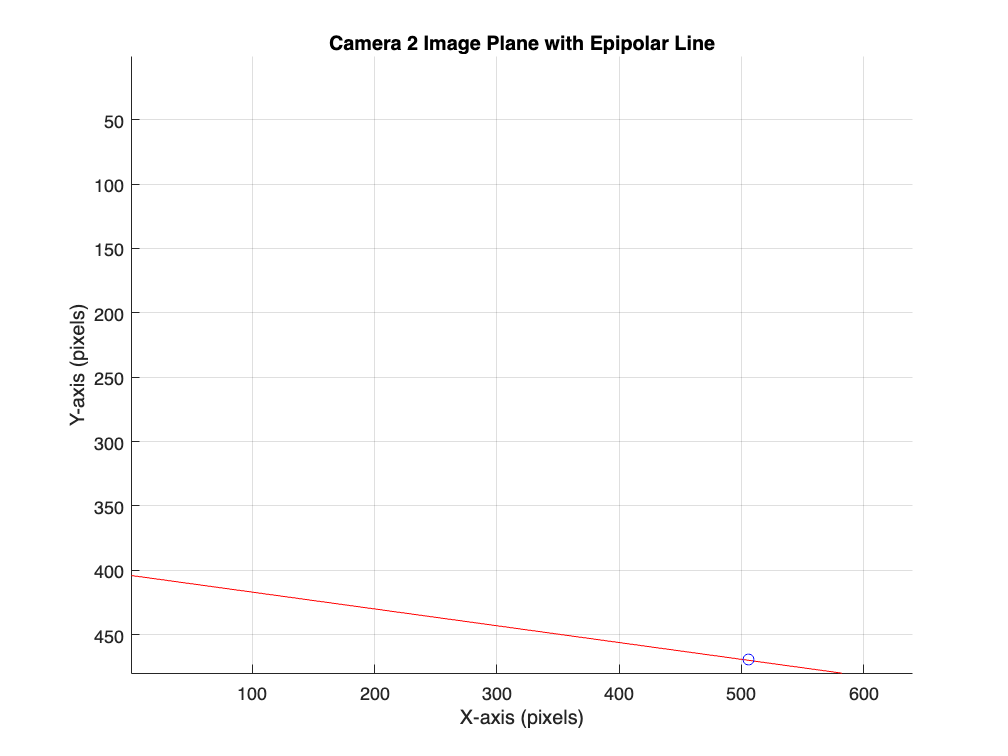


% Normalize the epipolar lines
l2 = l2 / norm(l2(1:2));
l1 = l1 / norm(l1(1:2));

% Camera 2's image dimensions - replace with actual values
imageWidthC2 = 640;  % Width of Camera 2's image
imageHeightC2 = 480; % Height of Camera 2's image
imageWidthC1 = 640;  % Width of Camera 2's image
imageHeightC1 = 480; % Height of Camera 2's image

% Feature pixel coordinate in Camera 2 - replace with actual value
featurePixelC2 = [UV2(1) UV2(2)]; % Pixel coordinate in Camera 2 (e.g., [x, y])
featurePixelC1 = [UV1(1) UV1(2)]; % Pixel coordinate in Camera 2 (e.g., [x, y])

% Create a figure for the plot
figure;
hold on;
axis([1 imageWidthC2 1 imageHeightC2]);
xlabel('X-axis (pixels)');
ylabel('Y-axis (pixels)');
title('Camera 2 Image Plane with Epipolar Line');

% Plot the epipolar line
x = 1:imageWidthC2;
y = -(l2(1)*x + l2(3)) / l2(2);
plot(x, y, 'r'); % Plot in red color

% Plot the feature point in Camera 2
plot(featurePixelC2(1), featurePixelC2(2), 'bo'); % Plot as a blue circle

% Additional settings for the plot
grid on;
axis ij; % To set the origin of the image plane at the top left corner
hold off;


% Given epipolar line coefficients a, b, and c from the line equation ax + by + c = 0
a = l2(1);
b = l2(2);
c = l2(3);

% Given feature point coordinates (x0, y0)
x0 = featurePixelC2(1);
y0 = featurePixelC2(2);

% Calculate the distance from the point to the line
distance = abs(a*x0 + b*y0 + c) / sqrt(a^2 + b^2);

% Display the distance
disp(['Min distance: ', num2str(distance), ' pixels']);

Min distance: 0.32749 pixels


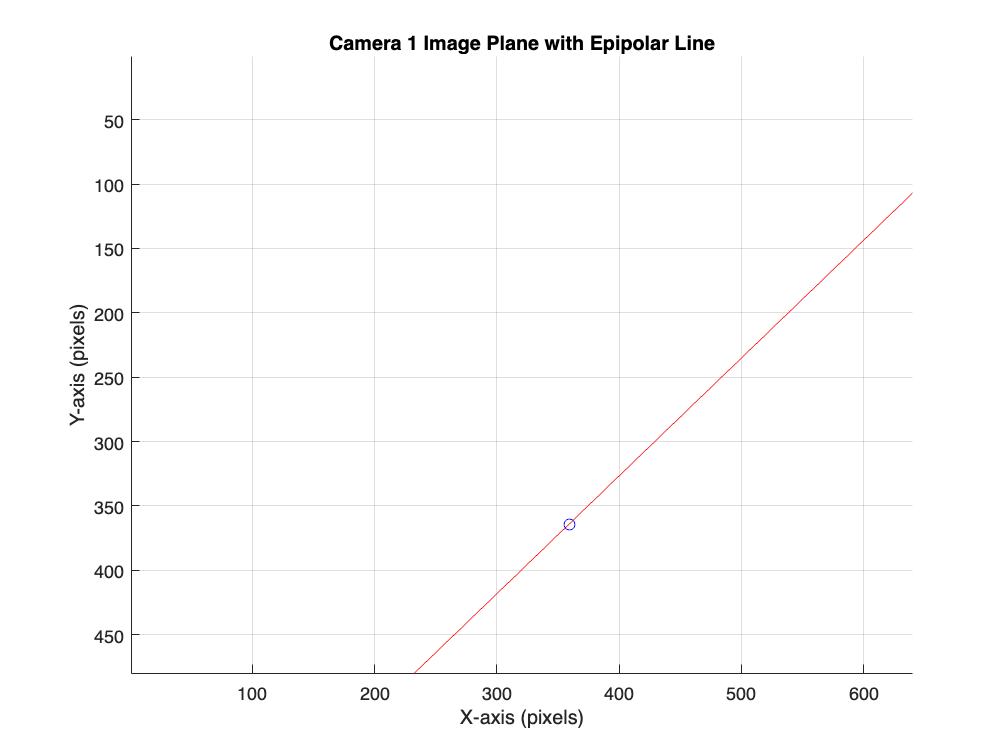


% Create a figure for the plot
figure;
hold on;
axis([1 imageWidthC1 1 imageHeightC1]);
xlabel('X-axis (pixels)');
ylabel('Y-axis (pixels)');
title('Camera 1 Image Plane with Epipolar Line');

% Plot the epipolar line
x = 1:imageWidthC1;
y = -(l1(1)*x + l1(3)) / l1(2);
plot(x, y, 'r'); % Plot in red color

% Plot the feature point in Camera 2
plot(featurePixelC1(1), featurePixelC1(2), 'bo'); % Plot as a blue circle

% Additional settings for the plot
grid on;
axis ij; % To set the origin of the image plane at the top left corner
hold off;


% Given epipolar line coefficients a, b, and c from the line equation ax + by + c = 0
a = l1(1);
b = l1(2);
c = l1(3);

% Given feature point coordinates (x0, y0)
x0 = featurePixelC1(1);
y0 = featurePixelC1(2);

% Calculate the distance from the point to the line
distance = abs(a*x0 + b*y0 + c) / sqrt(a^2 + b^2);

% Display the distance
disp(['Min distance: ', num2str(distance), ' pixels']);

Min distance: 0.22711 pixels


Epipolar lines of 3 features:

%INITIALIZE DATA

%GRAB DATA
flush(openmv1)
flush(openmv2)

openmv1.write('READY','string');
cam1_data = str2double(split(openmv1.readline(),','));
openmv2.write('READY','string');
cam2_data = str2double(split(openmv2.readline(),','));
UV_C1_SCRAMBLED = undistortPoints([cam1_data(1) cam1_data(2); cam1_data(3) cam1_data(4); cam1_data(5) cam1_data(6)],cInt1)

UV_C1_SCRAMBLED =   436.4796  211.7010
   57.8917  294.7672
  264.5779  449.5073


UV_C2_SCRAMBLED = undistortPoints([cam2_data(1) cam2_data(2); cam2_data(3) cam2_data(4); cam2_data(5) cam2_data(6)],cInt2)

UV_C2_SCRAMBLED =   223.7474  107.6281
  158.9894  284.0752
  412.5042  319.0515



UV_C1_PREV = imagePoints1_undistorted(1:3,:)

UV_C1_PREV =   436.4910  209.6706
   57.9313  293.6740
  265.6438  449.4744


UV_C2_PREV = imagePoints2_undistorted(1:3,:)

UV_C2_PREV =   412.5042  319.0515
  222.6020  106.4123
  158.9894  284.0752



UV_C2 = zeros(3,2)

UV_C2 =      0     0
     0     0
     0     0


for k = 1:3
    smallest_diff = [100 100];
    for i = 1:3
        diff = abs(UV_C2_PREV(k,:)-UV_C2_SCRAMBLED(i,:))
        if norm(diff)<norm(smallest_diff)
            pos = i
            smallest_diff = diff
        end
    end
    UV_C2(k,:) = UV_C2_SCRAMBLED(pos,:)
end

diff =   188.7568  211.4235


diff =   253.5148   34.9763


diff = 1.0e-11 *

    0.1137    0.0398


pos = 3

smallest_diff = 1.0e-11 *

    0.1137    0.0398


UV_C2 =   412.5042  319.0515
         0         0
         0         0


diff =     1.1455    1.2157


pos = 1

smallest_diff =     1.1455    1.2157


diff =    63.6125  177.6629


diff =   189.9022  212.6392


UV_C2 =   412.5042  319.0515
  223.7474  107.6281
         0         0


diff =    64.7580  176.4472


diff = 1.0e-06 *

    0.2333    0.0367


pos = 2

smallest_diff = 1.0e-06 *

    0.2333    0.0367


diff =   253.5148   34.9763


UV_C2 =   412.5042  319.0515
  223.7474  107.6281
  158.9894  284.0752



UV_C1 = zeros(3,2)

UV_C1 =      0     0
     0     0
     0     0


for k = 1:3
    smallest_diff = [100 100];
    for i = 1:3
        diff = abs(UV_C1_PREV(k,:)-UV_C1_SCRAMBLED(i,:))
        if norm(diff)<norm(smallest_diff)
            pos = i
            smallest_diff = diff
        end
    end
    UV_C1(k,:) = UV_C1_SCRAMBLED(pos,:)
end

diff =     0.0114    2.0304


pos = 1

smallest_diff =     0.0114    2.0304


diff =   378.5994   85.0966


diff =   171.9132  239.8366


UV_C1 =   436.4796  211.7010
         0         0
         0         0


diff =   378.5483   81.9730


diff =     0.0396    1.0932


pos = 2

smallest_diff =     0.0396    1.0932


diff =   206.6466  155.8332


UV_C1 =   436.4796  211.7010
   57.8917  294.7672
         0         0


diff =   170.8358  237.7734


diff =   207.7521  154.7072


diff =     1.0659    0.0328


pos = 3

smallest_diff =     1.0659    0.0328


UV_C1 =   436.4796  211.7010
   57.8917  294.7672
  264.5779  449.5073



% Define the camera intrinsics and extrinsics
% Replace these with your actual values
K1 = cInt1.K; % Intrinsic matrix of Camera 1
K2 = cInt2.K; % Intrinsic matrix of Camera 2
R1 = camPose_1.R; % Rotation matrix of Camera 1 w.r.t world frame
R2 = camPose_2.R; % Rotation matrix of Camera 2 w.r.t world frame
t1 = camPose_1.Translation'; % Translation vector of Camera 1 w.r.t world frame
t2 = camPose_2.Translation'; % Translation vector of Camera 2 w.r.t world frame

% Compute the essential matrix
R = R2' * R1; % Relative rotation between Camera 1 and Camera 2
t = R2'*(t2 - t1);  % Relative translation between Camera 1 and Camera 2
T_x = [0 -t(3) t(2); t(3) 0 -t(1); -t(2) t(1) 0]; % Skew-symmetric matrix of t
E = T_x * R; % Essential matrix

% Compute the fundamental matrix
F = K2' \ E / K1; % Fundamental matrix
el2 = zeros(3,3)

el2 =      0     0     0
     0     0     0
     0     0     0


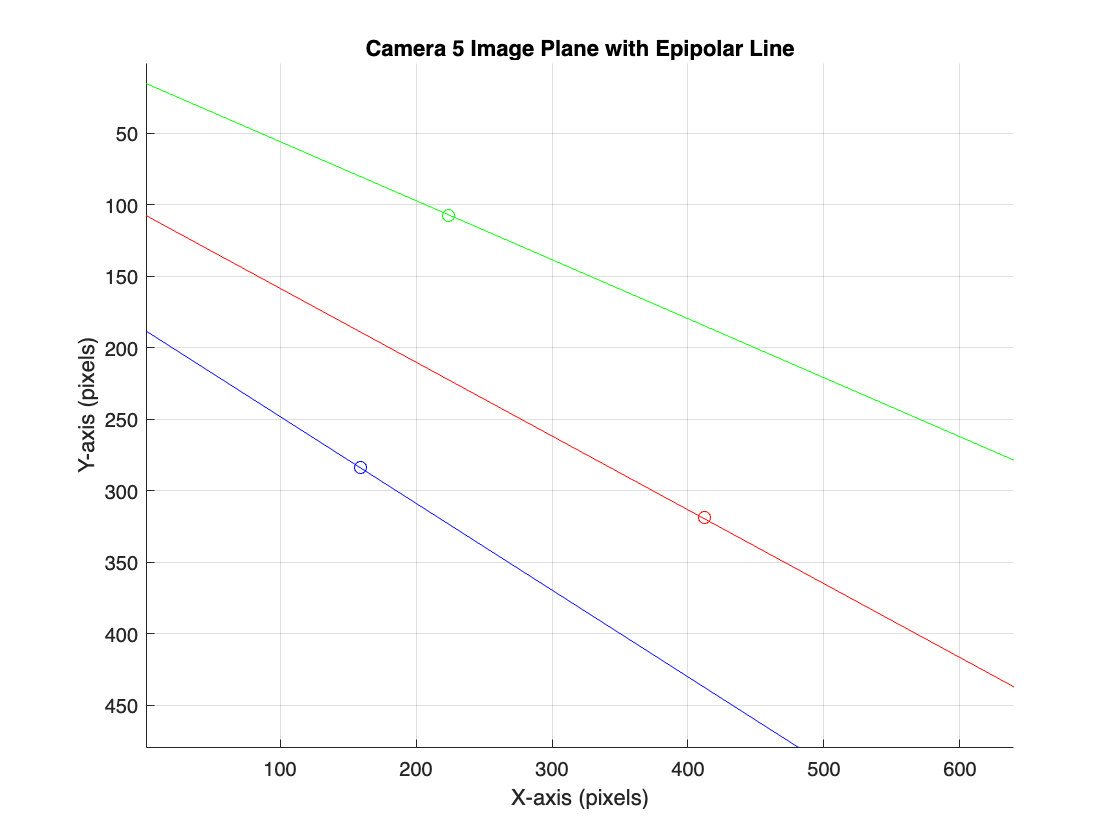

for k = 1:3 
    P_hom = [UV_C1(k,:) 1]';
    el2(:,k) = F*P_hom;
    el2(:,k) = el2(:,k)/norm(el2(1:2,k));
end
el2_check = epipolarLine()
% Create a figure for the plot
figure;
hold on;
axis([1 imageWidthC2 1 imageHeightC2]);
xlabel('X-axis (pixels)');
ylabel('Y-axis (pixels)');
title('Camera 5 Image Plane with Epipolar Line');

x = 1:imageWidthC2;
y = -(el2(1,1)*x + el2(3,1)) / el2(2,1);
plot(x, y, 'r'); % Plot in red color

% Plot the feature point in Camera 2
plot(UV_C2(1,1), UV_C2(1,2), 'ro'); % Plot as a blue circle

x = 1:imageWidthC2;
y = -(el2(1,2)*x + el2(3,2)) / el2(2,2);
plot(x, y, 'g'); % Plot in red color

% Plot the feature point in Camera 2
plot(UV_C2(2,1), UV_C2(2,2), 'go'); % Plot as a blue circle

x = 1:imageWidthC2;
y = -(el2(1,3)*x + el2(3,3)) / el2(2,3);
plot(x, y, 'b'); % Plot in red color

% Plot the feature point in Camera 2
plot(UV_C2(3,1), UV_C2(3,2), 'bo'); % Plot as a blue circle

% Additional settings for the plot
grid on;
axis ij; % To set the origin of the image plane at the top left corner
hold off;


feature_label = ["RED","GREEN","BLUE"];

feature_label = 1×3 string array
    "RED"    "GREEN"    "BLUE"


for k = 1:3 
    a = el2(1,k);
    b = el2(2,k);
    c = el2(3,k);
    x0 = UV_C2(k,1);
    y0 = UV_C2(k,2);
    distance = abs(a*x0 + b*y0 + c) / sqrt(a^2 + b^2);
    disp(['Min distance of feature ',num2str(k),': ', num2str(distance), ' pixels']);
end

Min distance of feature 1: 0.77628 pixels
Min distance of feature 2: 0.45474 pixels
Min distance of feature 3: 0.080211 pixels



%CAMERA 1
%_____________________________________
el1 = zeros(3,3)

el1 =      0     0     0
     0     0     0
     0     0     0


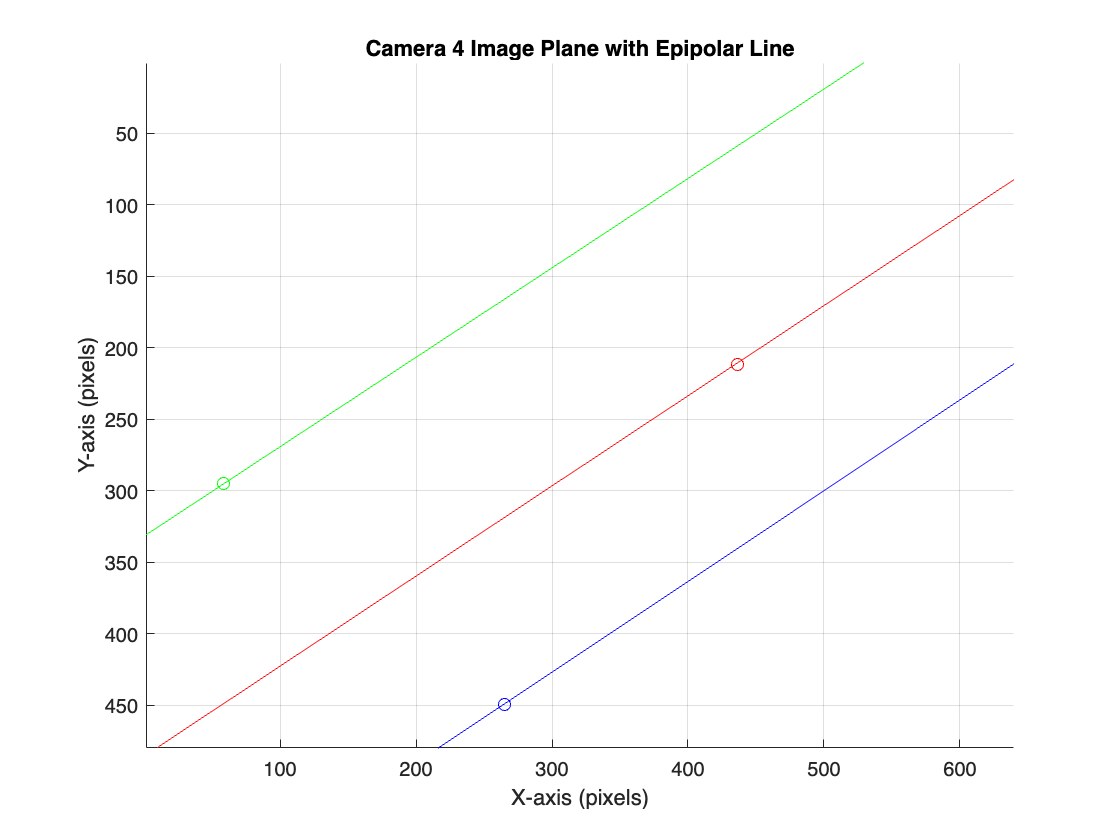

for k = 1:3 
    P_hom = [UV_C2(k,:) 1]';
    el1(:,k) = F'*P_hom;
    el1(:,k) = el1(:,k)/norm(el1(1:2,k));
end
% Create a figure for the plot
figure;
hold on;
axis([1 imageWidthC1 1 imageHeightC1]);
xlabel('X-axis (pixels)');
ylabel('Y-axis (pixels)');
title('Camera 4 Image Plane with Epipolar Line');

x = 1:imageWidthC1;
y = -(el1(1,1)*x + el1(3,1)) / el1(2,1);
plot(x, y, 'r'); % Plot in red color

% Plot the feature point in Camera 2
plot(UV_C1(1,1), UV_C1(1,2), 'ro'); % Plot as a blue circle

x = 1:imageWidthC2;
y = -(el1(1,2)*x + el1(3,2)) / el1(2,2);
plot(x, y, 'g'); % Plot in red color

% Plot the feature point in Camera 2
plot(UV_C1(2,1), UV_C1(2,2), 'go'); % Plot as a blue circle

x = 1:imageWidthC2;
y = -(el1(1,3)*x + el1(3,3)) / el1(2,3);
plot(x, y, 'b'); % Plot in red color

% Plot the feature point in Camera 2
plot(UV_C1(3,1), UV_C1(3,2), 'bo'); % Plot as a blue circle

% Additional settings for the plot
grid on;
axis ij; % To set the origin of the image plane at the top left corner
hold off;


for k = 1:3 
    a = el1(1,k);
    b = el1(2,k);
    c = el1(3,k);
    x0 = UV_C1(k,1);
    y0 = UV_C1(k,2);
    distance = abs(a*x0 + b*y0 + c) / sqrt(a^2 + b^2);
    disp(['Min distance of feature ',num2str(k),': ', num2str(distance), ' pixels']);
end

Min distance of feature 1: 0.82252 pixels
Min distance of feature 2: 0.57349 pixels
Min distance of feature 3: 0.10607 pixels


CORRESPONDANCE MATCHING, OF C5 in C4 FRAME. GIVEN (SCRAMBLED) DATA IN C5, I NEED TO UNSCRAMBLE THAT DATA AND THEN CHECK THE EPIPOLAR LINES IN C4 FRAME AND SET THE CORRESPONDING POINTS TO THE CORRECT POS:

%INITIALIZE DATA:
UV_C2_PREV = imagePoints2_undistorted(1:3,:);

%IN BFT EKF LOOP:
openmv1.write('READY','string');
cam1_data = str2double(split(openmv1.readline(),','));
openmv2.write('READY','string');
cam2_data = str2double(split(openmv2.readline(),','));
UV_C1_SCRAMBLED = undistortPoints([cam1_data(1) cam1_data(2); cam1_data(3) cam1_data(4); cam1_data(5) cam1_data(6)],cInt1)

UV_C1_SCRAMBLED =   436.4796  211.7010
   57.8917  294.7672
  264.5779  449.5073


UV_C2_SCRAMBLED = undistortPoints([cam2_data(1) cam2_data(2); cam2_data(3) cam2_data(4); cam2_data(5) cam2_data(6)],cInt2)

UV_C2_SCRAMBLED =   223.7474  107.6281
  158.9894  284.0752
  412.5042  319.0515



UV_C2 = zeros(3,2);
for k = 1:3
    smallest_diff = [100 100];
    for i = 1:3
        diff = abs(UV_C2_PREV(k,:)-UV_C2_SCRAMBLED(i,:))
        if norm(diff)<norm(smallest_diff)
            pos = i
            smallest_diff = diff
        end
    end
    UV_C2(k,:) = UV_C2_SCRAMBLED(pos,:)
end

diff =   188.7568  211.4235


diff =   253.5148   34.9763


diff = 1.0e-11 *

    0.1137    0.0398


pos = 3

smallest_diff = 1.0e-11 *

    0.1137    0.0398


UV_C2 =   412.5042  319.0515
         0         0
         0         0


diff =     1.1455    1.2157


pos = 1

smallest_diff =     1.1455    1.2157


diff =    63.6125  177.6629


diff =   189.9022  212.6392


UV_C2 =   412.5042  319.0515
  223.7474  107.6281
         0         0


diff =    64.7580  176.4472


diff = 1.0e-06 *

    0.2333    0.0367


pos = 2

smallest_diff = 1.0e-06 *

    0.2333    0.0367


diff =   253.5148   34.9763


UV_C2 =   412.5042  319.0515
  223.7474  107.6281
  158.9894  284.0752



UV_C2_PREV = UV_C2;

% Define the camera intrinsics and extrinsics
% Replace these with your actual values
K1 = cInt1.K; % Intrinsic matrix of Camera 1
K2 = cInt2.K; % Intrinsic matrix of Camera 2
R1 = camPose_1.R; % Rotation matrix of Camera 1 w.r.t world frame
R2 = camPose_2.R; % Rotation matrix of Camera 2 w.r.t world frame
t1 = camPose_1.Translation'; % Translation vector of Camera 1 w.r.t world frame
t2 = camPose_2.Translation'; % Translation vector of Camera 2 w.r.t world frame

% Compute the essential matrix
R = R2' * R1; % Relative rotation between Camera 1 and Camera 2
t = R2'*(t2 - t1);  % Relative translation between Camera 1 and Camera 2
T_x = [0 -t(3) t(2); t(3) 0 -t(1); -t(2) t(1) 0]; % Skew-symmetric matrix of t
E = T_x * R; % Essential matrix

% Compute the fundamental matrix
F = K2' \ E / K1; % Fundamental matrix

el1 = zeros(3,3)

el1 =      0     0     0
     0     0     0
     0     0     0


for k = 1:3 
    P_hom = [UV_C2(k,:) 1]';
    el1(:,k) = F'*P_hom;
    el1(:,k) = el1(:,k)/norm(el1(1:2,k));
end

for k = 1:3 
    a = el1(1,k);
    b = el1(2,k);
    c = el1(3,k);
    distance=zeros(3,1)
    for i = 1:3
        x0 = UV_C1_SCRAMBLED(i,1);
        y0 = UV_C1_SCRAMBLED(i,2);
        distance(i) = abs(a*x0 + b*y0 + c) / sqrt(a^2 + b^2)
    end
    [val,pos] = min(distance)
    UV_C1(k,:) = UV_C1_SCRAMBLED(pos,:);
end

distance =      0
     0
     0


distance =     0.8225
         0
         0


distance =     0.8225
  130.6053
         0


distance =     0.8225
  130.6053
  110.4671


val = 0.8225

pos = 1

distance =      0
     0
     0


distance =   129.5539
         0
         0


distance =   129.5539
    0.5735
         0


distance =   129.5539
    0.5735
  240.1679


val = 0.5735

pos = 2

distance =      0
     0
     0


distance =   108.7126
         0
         0


distance =   108.7126
  241.2456
         0


distance =   108.7126
  241.2456
    0.1061


val = 0.1061

pos = 3

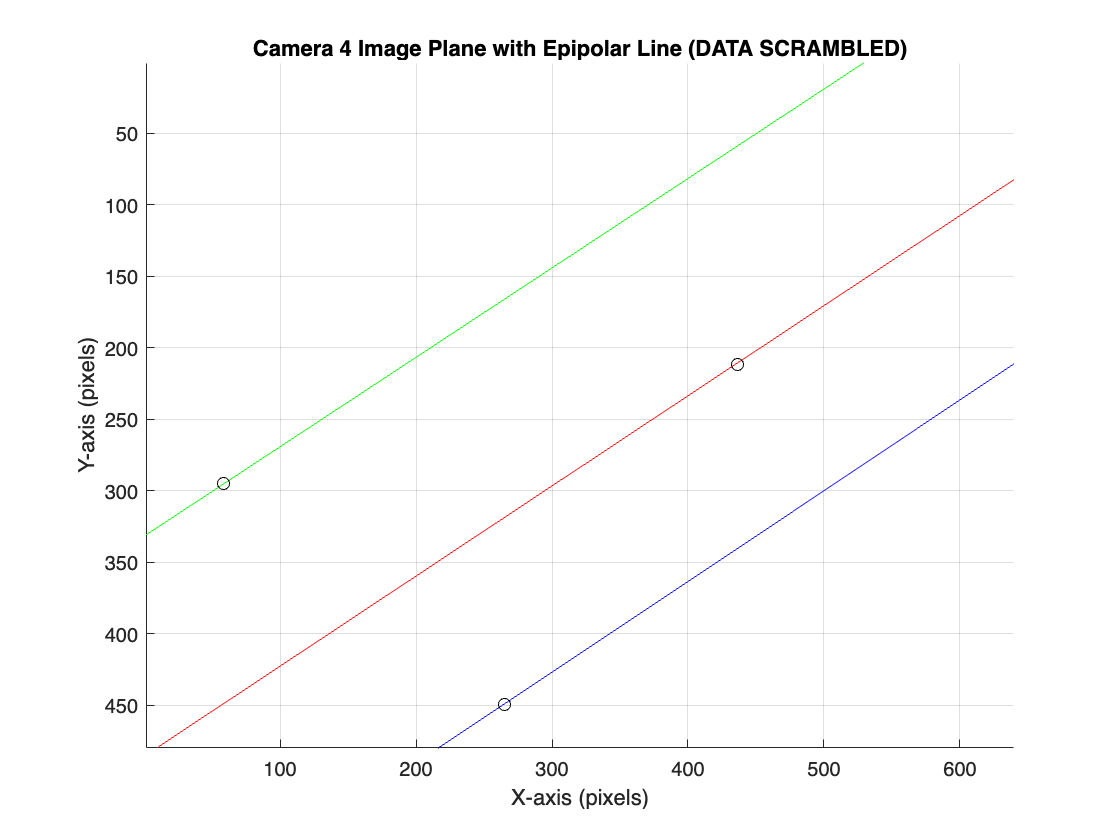


%SCRAMBLED PLOT
figure;
hold on;
axis([1 imageWidthC1 1 imageHeightC1]);
xlabel('X-axis (pixels)');
ylabel('Y-axis (pixels)');
title('Camera 4 Image Plane with Epipolar Line (DATA SCRAMBLED)');

x = 1:imageWidthC1;
y = -(el1(1,1)*x + el1(3,1)) / el1(2,1);
plot(x, y, 'r'); % Plot in red color

% Plot the feature point in Camera 2
plot(UV_C1_SCRAMBLED(1,1), UV_C1_SCRAMBLED(1,2), 'ko'); % Plot as a blue circle

x = 1:imageWidthC2;
y = -(el1(1,2)*x + el1(3,2)) / el1(2,2);
plot(x, y, 'g'); % Plot in red color

% Plot the feature point in Camera 2
plot(UV_C1_SCRAMBLED(2,1), UV_C1_SCRAMBLED(2,2), 'ko'); % Plot as a blue circle

x = 1:imageWidthC2;
y = -(el1(1,3)*x + el1(3,3)) / el1(2,3);
plot(x, y, 'b'); % Plot in red color

% Plot the feature point in Camera 2
plot(UV_C1_SCRAMBLED(3,1), UV_C1_SCRAMBLED(3,2), 'ko'); % Plot as a blue circle

% Additional settings for the plot
grid on;
axis ij; % To set the origin of the image plane at the top left corner
hold off;

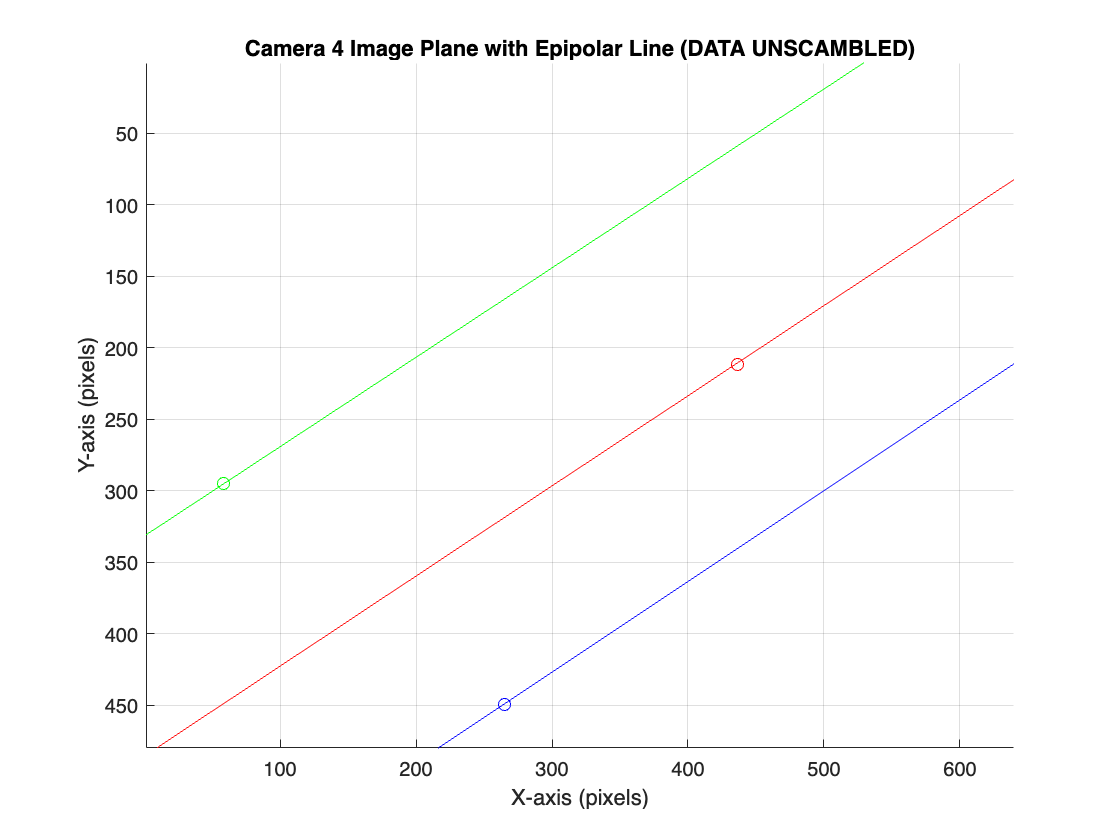




%UNSCRAMBLED PLOT
figure;
hold on;
axis([1 imageWidthC1 1 imageHeightC1]);
xlabel('X-axis (pixels)');
ylabel('Y-axis (pixels)');
title('Camera 4 Image Plane with Epipolar Line (DATA UNSCAMBLED)');

x = 1:imageWidthC1;
y = -(el1(1,1)*x + el1(3,1)) / el1(2,1);
plot(x, y, 'r'); % Plot in red color

% Plot the feature point in Camera 2
plot(UV_C1(1,1), UV_C1(1,2), 'ro'); % Plot as a blue circle

x = 1:imageWidthC2;
y = -(el1(1,2)*x + el1(3,2)) / el1(2,2);
plot(x, y, 'g'); % Plot in red color

% Plot the feature point in Camera 2
plot(UV_C1(2,1), UV_C1(2,2), 'go'); % Plot as a blue circle

x = 1:imageWidthC2;
y = -(el1(1,3)*x + el1(3,3)) / el1(2,3);
plot(x, y, 'b'); % Plot in red color

% Plot the feature point in Camera 2
plot(UV_C1(3,1), UV_C1(3,2), 'bo'); % Plot as a blue circle

% Additional settings for the plot
grid on;
axis ij; % To set the origin of the image plane at the top left corner
hold off;

function error = computeReprojectionError(pose, worldPoints, imagePoints, cParams)
    % Decompose Pose Parameters
    rotationVector = pose(1:3);
    translationVector = pose(4:6);

    % Project World Points to Image Plane using estimated pose
    projectedPoints = world2img(worldPoints, rigidtform3d([eul2rotm(rotationVector) translationVector'; 0 0 0 1]), cParams.Intrinsics);

    % Compute Reprojection Error
    error = projectedPoints - imagePoints;
    error = error(:); % Reshape to a vector for lsqnonlin
end
